# Vibrating String

## 1D Wave Equation

A vibrating string can be represented by the 1D wave equation. The 1D wave equations is


$$\frac{\partial^2 u}{\partial t^2} = c^2 \frac{\partial^2 u}{\partial x^2}$$
 

where $u(x,t)$ is the displacement of the string and the wavespeed $c$ is


$$c = \frac{T}{\rho}$$


where $T$ is the string tension and $\rho$ is the density.

Assuming that the string is fixed at both ends, $x=0$ and $x=L$ and that  the string is initially displaced according to a function $u_0(x)$ but has zero initial velocity, in mathematical terms:

$u(0,t) = u(L,t) = 0$,    $u(x,0) = u_0$,    and    $\left. \frac{\partial u}{\partial t} (x,0)= 0$

The solution is


$$u(x,t) = \sum_{n=1}^\infty
 a_n \cos\left( \frac{n \pi c}{L} t \right) \sin \left(\frac{n \pi}{L} x \right) $$


where the coefficients $a_n$ are determined by the initial displacement, $u_0$.

## Solution and visualization

**Physical constants**

First, define the physical constants.

L = 0.66; % Domain length (m) (guitar strings are 26 inches)
T = 67;
rho = 1e-3;

Nmodes = 10; % Number of Fourier modes used in the estimation

Fs = 44100;
tf = 0.5;
Nt = 44100*tf;

c = sqrt(T/rho);
p = 0.4; % Pluck position (m)
up = 0.05; % Displacement at the plucked location (m)
Nx = 200; % Points to plot/estimate integrals

x = linspace(0,L,Nx);
u0 = interp1([0,p,L],[0,up,0],x);

a = zeros(Nmodes,1);
for n = 0:(Nmodes-1)
    a(n+1) = 2/L*trapz(x,sin(n*pi/L*x).*u0);
end

n = (0:(Nmodes-1))';

% Spatial modes
X = sin(n*pi/L.*x);

% Construct solution
U = zeros(Nt,Nx);
t = linspace(0,tf,Nt)';
for nt = 1:Nt
    T = cos(n*pi*c/L.*t(nt));
    U(nt,:) = sum(a.*T.*X,1);
end


## Plot spatial signal

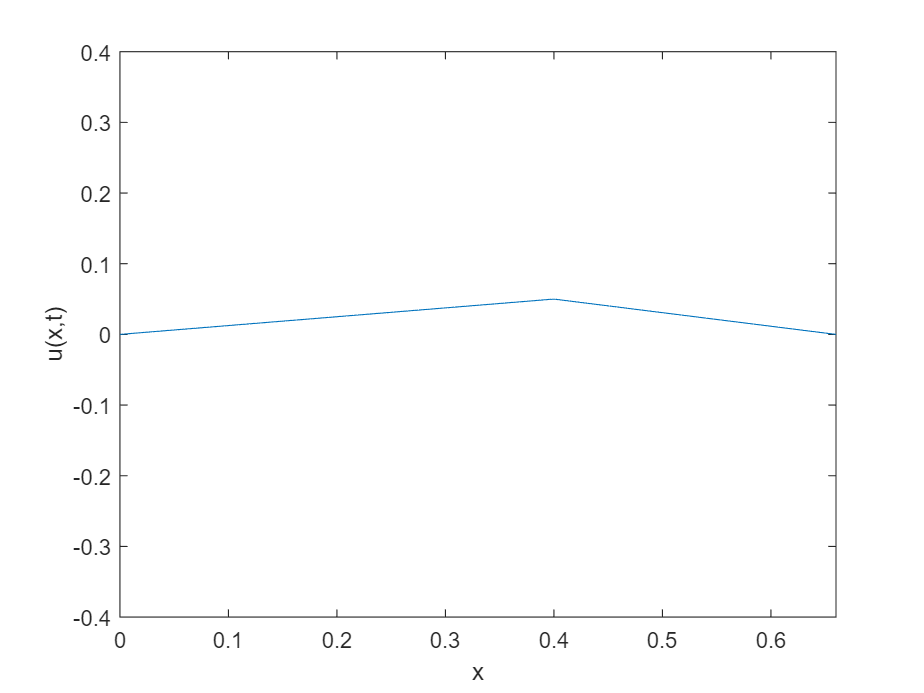

figure
ax = axes;
pHandle = plot(x,u0);
axis([0,L,-p,p])

ylabel('u(x,t)')
xlabel('x')


%% ANIMATED PLOT (REMOVE IF USING A LOT OF DATA POINTS)
% for nt = 1:Nt
%     u = U(nt,:);
%     pHandle.YData = u;
%     pause(0)
% end

## PDE discretized solution

https://aip.scitation.org/doi/pdf/10.1063/1.168621

          

L = 0.66; % Domain length (m) (guitar strings are 26 inches)
T = 67;
rho = 1e-3;

Fs = 44100;
tf = 0.5;
Nt = 44100*tf;

c = sqrt(T/rho);
p = 0.4; % Pluck position (m)
up = 0.05; % Displacement at the plucked location (m)
Nx = 100; % Points to plot/estimate integrals

x = linspace(0,L,Nx);
t = linspace(0,tf,Nt)';
y0 = interp1([0,p,L],[0,up,0],x);
dx = x(2)-x(1);
dt = t(2) - t(1);

r = c*dt/dx;

% Construct solution
Y = zeros(Nt,Nx);

% Initial values of the variable y
ynm1 = y0;
yn = y0;
ynp1 = y0;
for nt = 1:Nt
    
    % update y
    ynp1(2:end-1) = 2*(1-r^2).*yn(2:end-1) - ynm1(2:end-1) + r^2*(yn(3:end) + yn(1:end-2));
    
    % Store values
    ynm1 = yn;
    yn = ynp1;

    Y(nt,:) = yn;
end

% surf(Y)
% % ANIMATED PLOT (REMOVE IF USING A LOT OF DATA POINTS)
% figure
% ax = axes;
% pHandle = plot(x,y0);
% axis([0,L,-p,p])
% 
% ylabel('u(x,t)')
% xlabel('x')
% 
% for nt = 1:Nt
%     u = Y(nt,:);
%     pHandle.YData = u;
%     pause(0)
% end


## Temporal signal

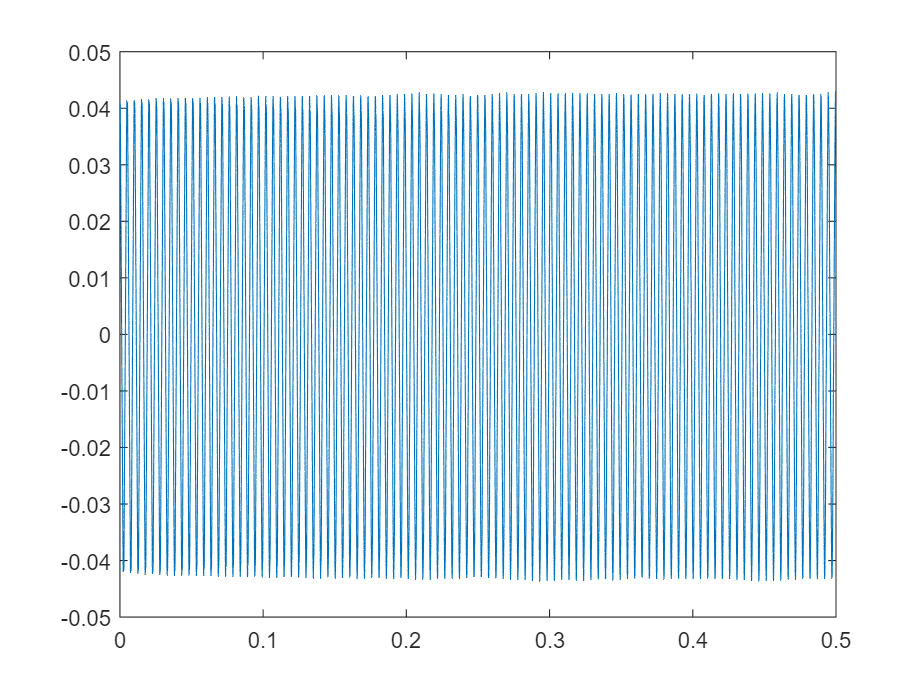

k = 50;
tc = t;
yc = Y(:,k);
plot(tc,yc)

## **Temporal Fourier series**

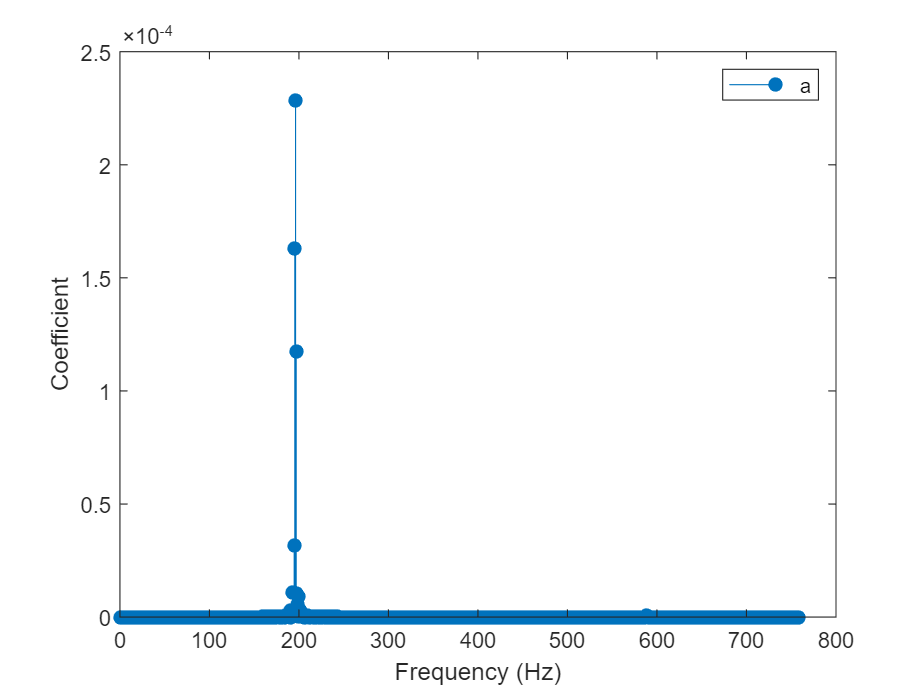

Nmodes = 1000; % Number of Fourier modes used in the estimation

a = zeros(1,Nmodes);
b = zeros(1,Nmodes);
a0 = 1/L*trapz(tc,yc);
for n = 1:Nmodes
    a(n) = 1/L*trapz(tc,cos(n*pi/L*tc).*yc);
    b(n) = 1/L*trapz(tc,sin(n*pi/L*tc).*yc);
end

% Frequencies
f = (1:Nmodes)/(2*L);

stem(f,b.^2 + a.^2,"filled")
xlabel("Frequency (Hz)")
ylabel("Coefficient")
legend("a","b")

Play the original sound

player = audioplayer(yc*5, Fs);
play(player);